# **Interfacial Excess**

**Calculate interfacial excess**

Materials often exhibit segregations of elements on interfaces. Therefore, the quantitative determination of the "excess number of solute atoms associated with this interface" (interfacial excess) delivers important insights. Basis of the function is the calculation of an integral curve as described by *Krakauer and Seidman.* 

Using a GUI, the user can define the exact location of two section for linear regression.

For the calculation of a interfacial excess value, the user needs to define an interface, which must be a 1x1 structure with fields of faces and vertices (hence often called fv), e.g., a grain boundary (see the live script ModellingGB).

Additionally, the pos file of the species (*posSpecies*), the parent pos file (*pos*). The described method is particularly helpful to quantify a few hundered atoms enriched at the interface. Therefore, reasonable statistics are of mutual importance. It is possible to calculate the interfacial excess values for predefined *vertices*, for example with sufficient distance from the border of the dataset. 

The function *patchCreateExcessValue* does not have an output. The determined interfacial excess is displayed in the figure (below integral curve) directly. 

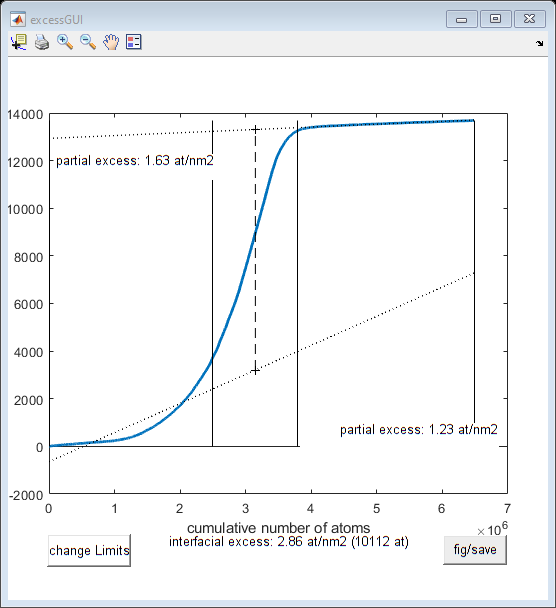

pos = pos; % selection of pos file (decomposed); must be present in the workspace
posSpecies = pos(pos.atom == 'B',:); % specification of wanted species, input as atomic symbol (e.g., C)
interface = fv; % input of interface structure; must be present in workspace
vertices = []; % input of vertices that define a specific region in the dataset

patchCreateExcessValue(posSpecies,pos,interface,vertices); % creation of proxigram

Pushbuttons (*change Limits, fig/save*) can be used to modify limits and to store the result (as figure).